clear
clc

% Initializing kero variables
KtL = 10.95; % Tank length
KtD = 8; % Tank diameter
KwM = 23.392248; % Wet mass
KdM = 10.992248; % Dry mass
Kdensity = 0.02962444; % Propellant density lbm/in^3
Kmdot = 1.24; % Mass flow rate

% Initializing lox variables
LtL = 10.95; % Tank length
LtD = 8; % Tank diameter
LwM = 28.392248; % Wet mass
LdM = 10.992248; % Dry mass
Ldensity = 0.0416403168; % Propellant density lbm/in^3
Lmdot = 1.74; % Mass flow rate

% Initializing n2 variables
NtL = 20.4; % Tank Length
NtD = 6.3; % Tank Diameter
NwM = 9.92; % Wet mass
NdM = 7.72; % Dry mass
Ndensity = 0.00796751298; % Propellant density lbm/in^3
Nmdot = 0.22; % Mass flow rate lbm/s

time = 10; % Burn time
burntime = linspace(0,time,11);


% Calling function
N2CoGs = getCoG(NwM, NdM, time, NtL, NtD, Ndensity, Nmdot);
T = array2table(N2CoGs,"VariableNames",{'Time (s)','CoG (in from base of tank)'});
T = table(T,'VariableNames',{'N2 CG'});
disp(T)

                    N2 CG                 
    Time (s)    CoG (in from base of tank)
    ______________________________________

        0                 17.379          
        1                 17.062          
        2                 16.748          
        3                 16.437          
        4                  16.13          
        5                 15.827          
        6                 15.527          
        7                 15.231          
        8                 14.939          
        9                 14.652          
       10                 14.369          



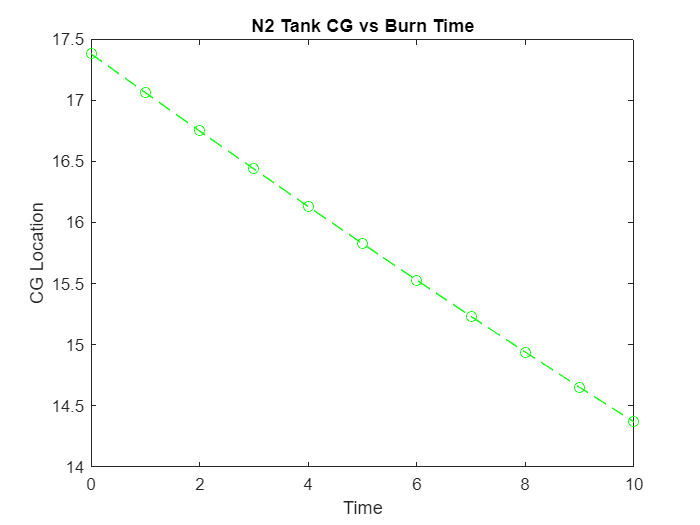

plot(burntime, N2CoGs(:,2),'g--o')
title("N2 Tank CG vs Burn Time")
ylabel('CG Location')
xlabel('Time')


KeroCoGs = getCoG(KwM, KdM, time, KtL, KtD, Kdensity, Kmdot);
T = array2table(KeroCoGs,"VariableNames",{'Time (s)','CoG (in from base of tank)'});
T = table(T,'VariableNames',{'Kero CG'});
disp(T)

                   Kero CG                
    Time (s)    CoG (in from base of tank)
    ______________________________________

        0                 7.8954          
        1                 7.5746          
        2                 7.2612          
        3                 6.9561          
        4                 6.6604          
        5                 6.3753          
        6                 6.1023          
        7                 5.8431          
        8                 5.5999          
        9                 5.3752          
       10                 5.1721          



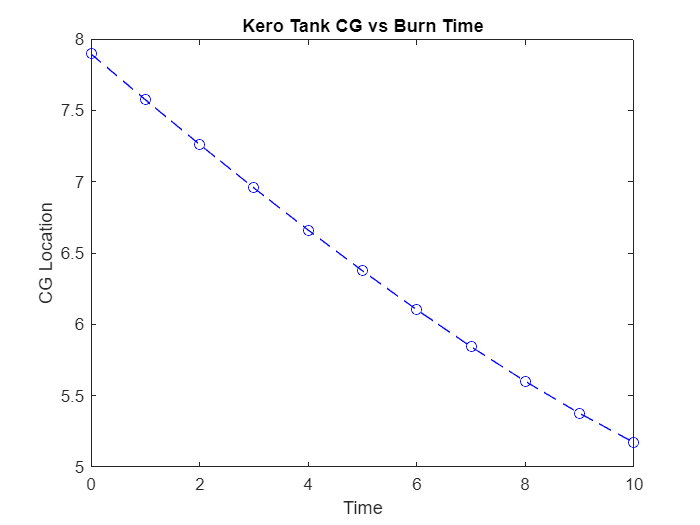

plot(burntime, KeroCoGs(:,2),'b--o')
title("Kero Tank CG vs Burn Time")
ylabel('CG Location')
xlabel('Time')

LOXCoGs = getCoG(LwM, LdM, time, LtL, LtD, Ldensity, Lmdot);
T = array2table(LOXCoGs,"VariableNames",{'Time (s)','CoG (in from base of tank)'});
T = table(T,'VariableNames',{'LOX CG'});
disp(T)

                    LOX CG                
    Time (s)    CoG (in from base of tank)
    ______________________________________

        0                 7.1509          
        1                 6.8267          
        2                 6.5113          
        3                  6.206          
        4                 5.9127          
        5                 5.6332          
        6                 5.3701          
        7                 5.1265          
        8                 4.9064          
        9                  4.715          
       10                 4.5591          



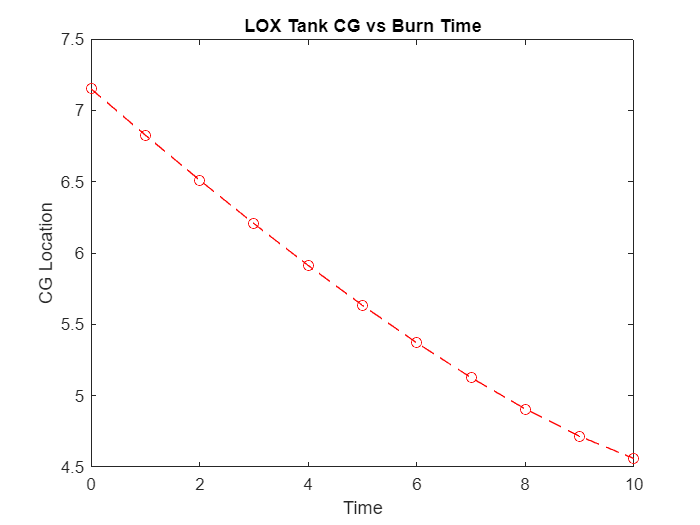

plot(burntime, LOXCoGs(:,2),'r--o')
title("LOX Tank CG vs Burn Time")
ylabel('CG Location')
xlabel('Time')

function [CoGs] = getCoG(wM, dM, time, tL, tD, density, mdot)

Vo = (wM / density) * (1.15); % Finds initial propellant volume
tCG = dM * (tL/2); % Finds constant W1d1/tank term in COG equation
tR = tD / 2; % Converts tank diameter to radius

V = zeros(1,(round(time) + 1)); % Preallocates arrays for variables that change with time
mp = V;
d = V;
COG = V;
% Done preallocating (for now), it's loop time yippee
for t = (0:time)
    mp(t+1) = wM - (mdot * t); % Finds propellant mass at t
    d(t+1) = ((Vo - ((mdot/density)*t)) / (2 * pi * ((tR) ^ 2))); % Finds the distance term for the propellant at t
    COG(t+1) = ((tCG + (mp(t+1) * d(t+1))) / (dM + mp(t+1))); % Finds (finally) the center of gravity at t
end
CoGs = zeros((round(time) + 1),2); % Preallocates space for CoGs table
CoGs(:,1) = 0:(round(time)); % Makes column of time values
CoGs(:,2) = COG; % Makes column of CoG values

end